# Worksheet 3, Part 2: Replicating Scientific Results

*Important Note:* Worksheet 3 comes to you in just **two parts**; `worksheet3_part1_assignment.mlx` and `worksheet3_part2_assignment.mlx`

*Learning Objectives:* As a result of working through this notebook, you will learn:

- The importance of *replication* to the process of science.

- How numerical methods parameters affect the *stability* of computer-simulated results.

- How a reasonable validation of a model can be done without direct comparison against data.

## Replication of Phillips (1996)

We will continue working with the Phillips (1996) paper (available from the Readings folder on Canvas). Last time we did a *guided reading* of this paper. Next, we are going to *replicate* the key findings from his paper.

*Replication* is the process of an independent researcher repeating the same experiment from a published paper with the goal of obtaining the same or similar findings. Replication is a key step in the process of science. You're going to practice doing real scientific work in this notebook!

Up first—we never build a model just for its own sake. We always build a model to answer a scientific question. To that end, let's remind ourselves of Phillips' modeling question.

### Exercise 1 / 5

Remind me: What was Phillips' modeling question in this paper? What type of question is this? (Explanation, prediction, or design?)

- *(Summarize the modeling question here) *Does the concentration of HIV in a person's plasma show the same trends whether or not there is a removal of free virions?

- *(Categorize the modeling question here)*

This is an explanation question.

## Implementing the model

Last time you studied the action equations from Phillips' model, and used Euler's Method to translate them from continuous to discrete equations. For convenience, here are the discrete action equations for Phillips' model:


$$\begin{array}{rcl}
R_{t+1} &=& R_t + \Delta t \left( \Gamma \tau - \mu R_t - \beta R_t V_t \right) \\
L_{t+1} &=& L_t + \Delta t \left( \rho \beta R_t V_t - \mu L_t - \alpha L_t \right)\\
E_{t+1} &=& E_t + \Delta t \left( (1-\rho) \beta R_t V_t + \alpha L_t - \delta E_t \right)\\
V_{t+1} &=& V_t + \Delta t \left( \pi E_t - \sigma V_t \right)
\end{array}$$


*Note:* I've corrected the $p = \rho$ typo in the equations.

Your first task is to implement these equations in MATLAB code.

### Exercise 2 / 5

Complete the code at the bottom of this notebook to implement the action equations. Run the following code to check your work.

*Note:* You will need to scroll to the bottom of this worksheet to implement the function, then scroll back up!

% NOTE: Do not edit this code!
%       Use this to check your work

% Flow parameters
Gamma = 1.36;  % (1/day), rate at which uninfected CD4 lymphocytes are born
mu = 1.36e-3;  % (1/day), HIV-independent death rate of CD4 lymphocytes
tau = 0.2;     % (1), proportion of CD4 lymphocytes that are activated
beta = 2.7e-4; % (1/virion), rate of infection of CD4 lymphocytes
rho = 0.1;     % (1), proportion  of CD4 lymphocytes becoming latently infected upon infection
alpha = 3.6e-2;% (1/day), activation rate of latently infecte CD4 lymphocytes
sigma = 2;     % (1/day), death rate of cell-free virus particles (virions)
delta = 0.33;  % (1/day), death rate of actively infected CD4 lymphocytes
pi = 100;      % (1/day), rate of production of virions by an actively infected CD4 lymphocyte
% Initial conditions
R0 = 200;  % Activated, uninfected CD4 lymphocytes
L0 = 0;    % Activated, latently-infected CD4 lymphocytes
E0 = 0;    % Activated, actively-infected CD4 lymphocytes
V0 = 4e-7; % Virions (free viral particles)
% Simulation parameters
delta_t = 1; % (day) Timestep

% Run your action function
[Rn, Ln, En, Vn] = action_hiv(R0,L0,E0,V0,Gamma,mu,tau,beta,rho,alpha,sigma,delta,pi,delta_t)
  

Rn = 200.0000

Ln = 2.1600e-09

En = 1.9440e-08

Vn = 1.2000e-06

Rn = 200.0000

Ln = 2.1600e-09

En = 1.9440e-08

Vn = 1.2000e-06

    

% Assertions
assert(abs(Rn - 200) / Rn <= 1e-3, 'Incorrect value of Rn')
assert(abs(Ln - 2.16e-9) / Ln <= 1e-3, 'Incorrect value of Ln')
assert(abs(En - 1.944e-8) / En <= 1e-3, 'Incorrect value of En')
disp('Assertions passed!')

Assertions passed!


## Numerical Methods and Stability

Remember that we used an approximation (Euler's Method) to convert a differential equation into discrete equations. This introduces a numerical methods parameter $\Delta t$ that has no physical meaning, but rather controls the quality of the approximation. This $\Delta t$ parameter is important for controlling the *stability* of the numerical approximation.

To illustrate, let's consider a simple example: Imagine we wanted to simulate the following differential equation

$\frac{dY}{dt} = -3Y$.

Since the change in $Y$ is negatively proportional to its value, we would expect $Y$ to smoothly decrease towards zero.

Applying Euler's Method yields the following update rule

$Y_{i+1} = Y_i - 3 \Delta t Y_i$.

The following code simulates the model for a short period of time:

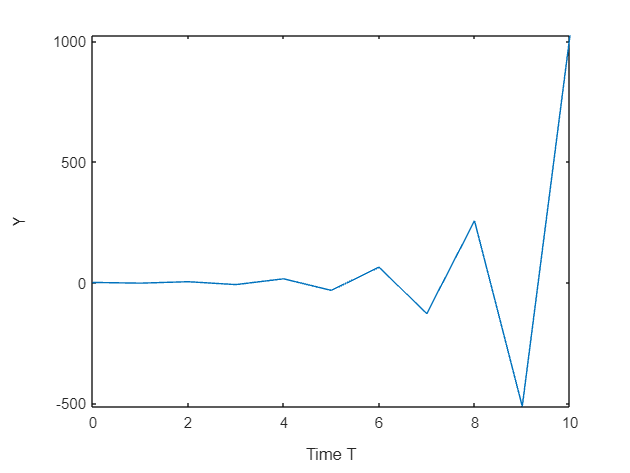

% Set a huge timestep
dt = 1;

% Simulate
T = 0:dt:10;
Y_all = zeros(size(T)); Y_all(1) = 1;
for i = 1:(length(Y_all) - 1)
    Y_all(i+1) = Y_all(i) - 3 * dt * Y_all(i);
end

% Plot
figure()
plot(T, Y_all);
xlabel('Time T')
ylabel('Y')

Instead of decaying smoothly, $Y$ "bounces" from negative to positive values of increasing magnitude. This is because the simulation is *unstable*.

We can stabilize the simulation by setting a smaller timestep:

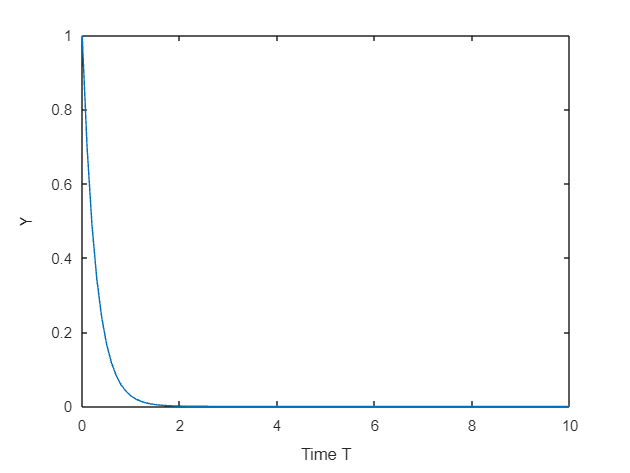

% Set a smaller timestep
dt = 1 / 10;

% Simulate
T = 0:dt:10;
Y_all = zeros(size(T)); Y_all(1) = 1;
for i = 1:(length(Y_all) - 1)
    Y_all(i+1) = Y_all(i) - 3 * dt * Y_all(i);
end

% Plot
figure()
plot(T, Y_all);
xlabel('Time T')
ylabel('Y')

Note that this decays towards zero smoothly, as we predicted above.

Up next you'll use this idea of stability to tune the timestep parameter for Phillips' model.

### Exercise 3 / 5

Compare the simulation results plotted below against the results shown in Figure 1 of Phillips (1996). Select a timestep `delta_t` that is small enough that the results match those of Phillips. Answer the questions below.

*Hint: *By adjusting the timestep `delta_t`, it is possible to re-create the results from Phillips (1996) Figure 1.

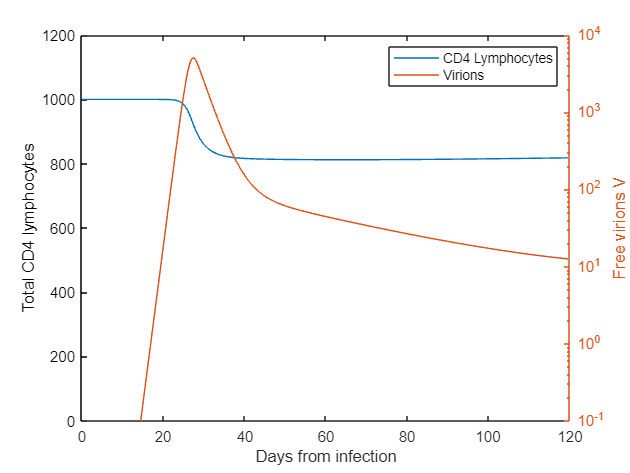

% TODO: Edit the timestep parameter to obtain stable results
delta_t = 0.5; 

% NOTE: Do not edit this code; use T
%       
t_end = 120;         % days, simulation duration
T = 0:delta_t:t_end; % Use this as your time values

R_all = zeros(size(T)); R_all(1) = R0;
L_all = zeros(size(T)); L_all(1) = L0;
E_all = zeros(size(T)); E_all(1) = E0;
V_all = zeros(size(T)); V_all(1) = V0;

% Simulate the model
for i = 1:length(T)-1
    [R_all(i+1), L_all(i+1), E_all(i+1), V_all(i+1)] = action_hiv( ...
        R_all(i), ...
        L_all(i), ...
        E_all(i), ...
        V_all(i), ...
        ...
        Gamma, ...
        mu, ...
        tau, ...
        beta, ...
        rho, ...
        alpha, ...
        sigma, ...
        delta, ...
        pi, ...
        ...
        delta_t ...
    );
end

% NOTE: Do not edit this code; this will re-create the plots from the
% Phillips (1996) paper. Use these to check your work.
CD4 = 1000*(1-tau) + R_all + L_all + E_all;

figure()
clf
plot(T, CD4, 'DisplayName', 'CD4 Lymphocytes')
xlabel('Days from infection')
ylabel('Total CD4 lymphocytes')
xlim ([0,120])
ylim([0 1200])
yyaxis right
semilogy(T, V_all, 'DisplayName', 'Virions')
ylabel('Free virions V')
ylim([1e-1 1e4])
legend()

figure()
clf
plot(T, R_all)

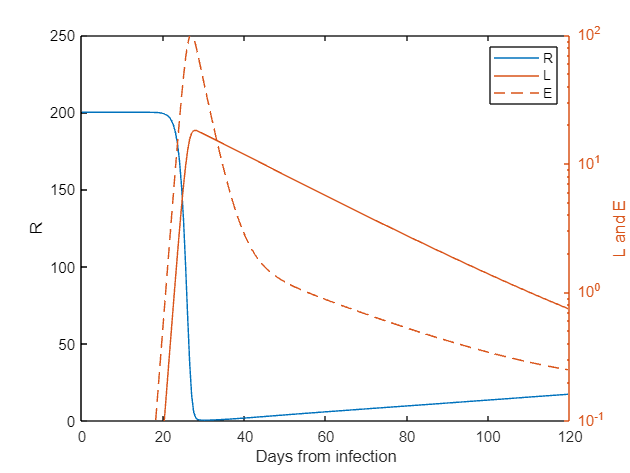

xlabel('Days from infection')
ylabel('R')
ylim([0 250])
yyaxis right
semilogy(T, [L_all', E_all'])
ylabel('L and E')
ylim([1e-1 1e2])
legend('R', 'L', 'E')

- What is the value of the $V$ stock at $120$ days from infection reported in the Phillips (1996) paper? What value did you obtain? Did they match?

-  *(Write your response here) *The value of the V stock in Phillips' paper was 10, my value was also 10. They did match.

- Do your simulated results exhibit the "peak-then-decline" behavior of HIV particles described in the Phillips (1996) paper?

-  *(Write your response here) *Yes

- In patients with HIV, their count of CD4 lymphocytes declines over a long period of time (longer than a month). Do your simulated results exhibit this steady, long-term decline of CD4 lymphocytes?

-  *(Write your response here) *Yes

## Conceptual Validation

The work we did above is a form of verification; getting our replicated results to match published results suggests that we implemented the model correctly. However, we also need to *validate* our model before it is trustworthy.

Let's remind ourselves of the definition of validation:

- *Validation:* The process of determining the degree to which a model is an accurate representation of the real world from the perspective of the intended uses of the model.

The intended use of a model is to answer a modeling question. Note that the definition of validation tells us that perfect accuracy is not necessary—we only need accuracy that is relevant to the question we aim to answer. We've talked about *different kinds* of modeling questions (prediction, explanation, design)—these different kinds of questions require different kinds of accuracy. Directly matching trends in measured data is not the only way to validate a model. 

It is important to note that Phillips' paper was published (in *Science*, no less!)—this means his modeling work was considered validated by professional scientists. In the next exercise, you'll study how Phillips validated his model by comparing specific, qualitative behaviors against relevant physical behaviors.

### Exercise 4 / 5

Answer the following questions. Note that you will need to read the paper to answer some of these!

- For the purposes of the modeling question, does the model need to be able to make patient-specific *predictions*? Or is it only necessary for us to have a more general *explanation*? *Note:* You will need to refer back to the modeling question to answer this!

-  *(Write your response here) *It's only necessary for us to have a more general explanation since the modeling question already assumes that normally there is a certain trend that is observed in patients. The only purpose of the model is to determine whether or not this trend will still be observed when there is no immune response at all. If it still is, then it can be assumed that this trend isn't due to immune response, thus answering our modeling question.

- How does Phillips present the real-world behavior in the count of virions in an HIV patient? Does he show graphs? Or does he describe the behavior in words?

-  *(Write your response here) *He describes it in words.

- Do Phillips' results correctly reproduce the real-world short-term qualitative behavior in the count of virions? (*Note:* Qualitative means "the general trend," not "the specific numbers according to a dataset.")

-  *(Write your response here) *Yes

Read the following quote from Phillips (1996):

> "Thus, although this simple model appears to capture the essenitial elements of primary HIV infection, it does not explain (nor attempt to explain) how HIV infection leads to gradual CD4 lymphocyte depletion after acute HIV infection."

- Did the author (Phillips) intend to match the long-term decay in the count of CD4 lymphocytes using his model?

-  *(Write your response here) *No

- Does the model need to match the long-term decay in the count of CD4 lymphocytes in order to answer the modeling question driving the paper?

-  *(Write your response here) *No, because the model is only asking about short-term trends.

- What evidence does the author (Phillips) present to make the case that his model is valid?

-  *(Write your response here)*

He says that it captures the essential elements of primary HIV infection except for the gradual depletion, however that was not its purpose and he makes that clear.

### Exercise 5 / 5

Respond to the following prompts.

- Summarize Phillips' modeling question and his answer in ABT form.

-  *(Write your response here) *After infection with HIV, the concentration of the virus in a person's plasma increases, then decreases a few weeks later, but a model with no removal of virus-infected cells still predicts this same behavior. Therefore, this behavior is probably not reflective of the body's ability to fight off infection.

- Does Phillips' paper prove that a specific immune response does not contribute at all to the short-term trends in HIV simulated here? Why or why not?

-  *(Write your response here)*

No, because the only way to prove for a fact that immune responses have nothing to do with the trends would be to simulate it in a lab with actual virus particles.

## Helper Functions (Exercise 2)

This is where you must implement the discrete action equations. For convenience, they are repeated here:


$$\begin{array}{rcl}
R_{t+1} &=& R_t + \Delta t \left( \Gamma \tau - \mu R - \beta R V \right) \\
L_{t+1} &=& L_t + \Delta t \left( \rho \beta R V - \mu L - \alpha L \right)\\
E_{t+1} &=& E_t + \Delta t \left( (1-\rho) \beta R V + \alpha L - \delta E \right)\\
V_{t+1} &=& V_t + \Delta t \left( \pi E - \sigma V \right)
\end{array}$$


Complete the following code.

*Note:* A reasonable programming language would allow you to define a function just before usage. MATLAB is not a reasonable programming language... Hence the need to jump down here to complete Exercise 2!

% TODO: Complete this function as part of Exercise 2

function [Rn, Ln, En, Vn] = action_hiv(R0,L0,E0,V0,Gamma,mu,tau,beta,rho,alpha,sigma,delta,pi,delta_t )
  

% Updates the state of the HIV model
%
% Usage
%     [Rn, Ln, En, Vn] = action_hiv(R, L, E, V, ...
%                          Gamma, mu, tau, beta, rho, ...
%                          alpha, sigma, delta, pi, delta_t, ...
%                        )
%
% Inputs
% (Flow parameters)
%   Gamma (1/day), rate at which uninfected CD4 lymphocytes are born
%   mu (1/day), HIV-independent death rate of CD4 lymphocytes
%   tau (1), proportion of CD4 lymphocytes that are activated
%   beta (1/virion), rate of infection of CD4 lymphocytes
%   rho (1), proportion  of CD4 lymphocytes becoming latently infected upon infection
%   alpha (1/day), activation rate of latently infecte CD4 lymphocytes
%   sigma (1/day), death rate of cell-free virus particles (virions)
%   delta (1/day), death rate of actively infected CD4 lymphocytes
%   pi (1/day), rate of production of virions by an actively infected CD4 lymphocyte
% (Initial conditions)
%   R0 Activated, uninfected CD4 lymphocytes
%   L0 Activated, latently-infected CD4 lymphocytes
%   E0 Activated, actively-infected CD4 lymphocytes
%   V0 Virions (free viral particles)
% (Numerical methods parameters)
%   delta_t (days), timestep (for Euler's Method)
%
% Returns
%   Rn Updated count of: Activated, uninfected CD4 lymphocytes
%   Ln Updated count of: Activated, latently-infected CD4 lymphocytes
%   En Updated count of: Activated, actively-infected CD4 lymphocytes
%   Vn Updated count of: Virions (free viral particles)

% (WRITE YOUR CODE HERE)
Rn = R0 + delta_t*(Gamma*tau - mu*R0 - beta*R0*V0);
Ln = L0 + delta_t*(rho*beta*R0*V0 - mu*L0 - alpha*L0);
En = E0 + delta_t*((1-rho)*beta*R0*V0 + alpha*L0 - delta*E0);
Vn = V0 + delta_t*(pi*E0 - sigma*V0);
    % Enforce some invariants
    Rn = max(Rn, 0);
    Ln = max(Ln, 0);
    En = max(En, 0);
    Vn = max(Vn, 0);

end